# Image Processing - Display and Simple Manipulation

**Write a program to decimate a given image.**

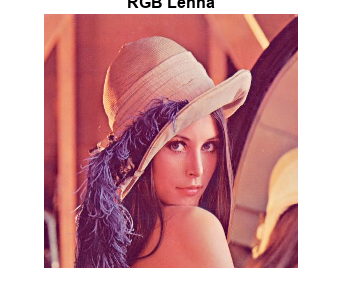

% Exercise - 1
clc;
clear;

%% Read image
img_rgb = imread('lenna.jpg');  % Read image
%% Display image
figure;
imshow(img_rgb )
title('RGB Lenna')

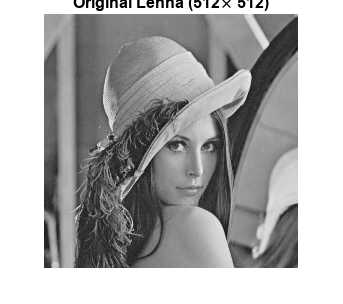



img_gray = rgb2gray(img_rgb);  % Convert to grayscale
[M, N] = size(img_gray); % Image Size



%% Decimate a given image by a factor of 2
rate = 2;
for i = 1 : M
   for j = 1 : N
       
   end
end


%% Display image
figure;
imshow(img_gray)
title('Original Lenna (512\times 512)')

**Write a program to interpolate the given image using average method.**

Image interpolation occurs when you resize or distort your image from one pixel grid to another. Image resizing is necessary when you need to increase or decrease the total number of pixels, whereas remapping can occur when you are correcting for lens distortion or rotating an image.

%% Interpolate image using average method
N = 5;
mask = ones(N, N) * 1/(N^2);
img_interp = conv2(img_gray, mask);
img_interp = uint8(img_interp);

%% Display image
figure;
imshow(img_gray)
title('Original Lenna (512\times 512)')

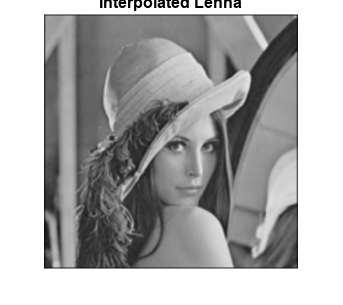


figure;
imshow(img_interp)
title('Interpolated Lenna')

**Write a program to**

- **Transpose an image**

- **Flip an image about the vertical axis**

- **Flip an image about the horizontal axis**

%% Transpose image


%% Flip image about vertical axis


%% Flip image about horizontal axis


%% Display image
figure;
imshow(img_gray)
title('Original Lenna (512\times 512)')


figure;
imshow(img_transpose)

Unrecognized function or variable 'img_transpose'.

title('Transposed Lenna (512\times 512)')

figure;
imshow(img_vertical)
title('Vertically flipped Lenna (512\times 512)')

figure;
imshow(img_horizontal)
title('Horizontally flipped Lenna (512\times 512)')

**Write a program to resize an image using inbuilt function **`imresize`**.**

%% Resize image


%% Display image
figure;
imshow(img_gray)
title('Original Lenna (512\times 512)')

figure;
imshow(img_resized)
title('Resized Lenna (256\times 256)')

**Write a program to rotate an image using inbuilt function **`imrotate`**.**

%% Resize image


%% Display image
figure;
imshow(img_gray)
title('Original Lenna (512\times 512)')

figure;
imshow(img_rotated)
title('Rotated Lenna (512\times 512)')

**Write a program to convert a grayscale image to binary (thresholding).**

%% Binarize image
threshold = 100;


%% Display image
figure;
imshow(img_gray)
title('Original Lenna (512\times 512)')

figure;
imshow(img_binary)
title('Binary Lenna (512\times 512)')


**Write a program to extract a rectangular portion of an image using inbuilt function **`imcrop`**.**

%% Image cropping


%% Display image
figure;
imshow(img_gray)
title('Original Lenna (512\times 512)')

figure;
imshow(img_crop)
title('Cropped Lenna')

**Write a program to find the negative of an image.**

%% Negative image


%% Display image
figure;
imshow(img_gray)
title('Original Lenna (512\times 512)')

figure;
imshow(img_negative)
title('Negative Lenna (512\times 512)')

**A program to add 'Salt and Pepper' type of noise to an image [Refer help for inbuilt function **`imnoise`**], and then filter it using 'neighborhood averaging'.**

%% Corrupt image with 'Salt and Pepper' noise
img_noised = imnoise(img_gray, 'salt & pepper');

%% Neighbourhood-averaging filter
N = 5;
mask = ones(N, N) * 1/(N^2);
img_filtered = conv2(img_noised, mask);
img_filtered = uint8(img_filtered);

%% Display image
figure;
imshow(img_gray)
title('Original Lenna (512\times 512)')

figure;
imshow(img_noised)
title('Salt & Pepper noise added Lenna (512\times 512)')

figure;
imshow(img_filtered)
title('Neighbourhood-averaging on Salt & Pepper noise added Lenna')

**Write a function for median filtering of an image.**

%% Median filtering of an image
img_median_filtered = medianFilter2(img_gray, [5, 5]);

%% Display image
figure;
imshow(img_gray)
title('Original Lenna (512\times 512)')

figure;
imshow(img_median_filtered)
title('Median filtered Lenna (512\times 512)')
%% medianFilter2: 2-D Median filtering
% Performs zero-padding around edges.

**Red eye detection**

% Read the input image
img = imread('lenna.jpg');

% Convert the image to grayscale
grayImg = rgb2gray(img);

% Enhance the contrast of the grayscale image
enhancedImg = imadjust(grayImg);

% Detect red-eye regions using thresholding
redEyeMask = enhancedImg > 0.5; % Adjust the threshold value as needed

% Remove small objects (potential false detections)
redEyeMask = bwareaopen(redEyeMask, 100);

% Dilate the red-eye mask to fill in gaps
se = strel('disk', 5);
redEyeMask = imdilate(redEyeMask, se);

% Display the red-eye mask overlaid on the original image
overlayImg = img;
overlayImg(:,:,1) = uint8(redEyeMask) * 255;
figure;
imshow(overlayImg);

% Apply red-eye correction
redEyePixels = img(repmat(redEyeMask, [1, 1, size(img, 3)]));
redEyePixels(:, :, 1) = 0; % Set the red channel to 0

% Create a copy of the image and replace the red-eye pixels
correctedImg = img;
correctedImg(repmat(redEyeMask, [1, 1, size(img, 3)])) = redEyePixels;

% Display the corrected image
figure;
imshow(correctedImg);


figure;
imshow(img_decimated)
title('Decimated Lenna (256\times 256)')

function [output_image] = medianFilter2(input_image, mask_size)
	% input_image: [M, N]
	% mask_size: [m, n]
	[M, N] = size(input_image);
	m = mask_size(1); n = mask_size(2);

	zero_padded_input_image = padarray(input_image, [floor(m/2), floor(n/2)]);
	output_image = zeros(M, N);

	for i = 1 : M
		for j = 1 : N
			patches = zero_padded_input_image(i : i+m-1, j : j+n-1);
			output_image(i, j) = median(patches, 'all');
		end
	end

	output_image = uint8(output_image);
end